# Transmission Line Waveform Visualization

Copyright © 2025, The MathWorks, Inc.

Uses 100 bergeron lines connected in series to visualize transmission line reflections

Define parameters. We will model 50km segments for a combined length of 5000km in order to see full wavelengths.

bdclose all
clear

length = 50;

Ts = 1e-5;

R1 = 0.01;
R0 = 0.4;

L1 = 1e-3;
L0 = 4e-3;

C1 = 10e-9;
C0 = 8e-9;

Simulate system

mdl = 'bergeron_100_segments';

open_system(mdl)
out = sim(mdl);

Visualize response across the length of the line

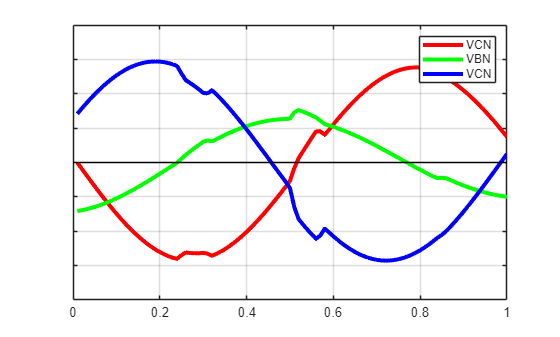

nt = numel(out.V.Time);

ns = size(out.V.Data,2);

VV = reshape(out.V.Data,ns,nt);
II = reshape(out.I.Data,ns,nt);

tt = (1:ns/3)/(ns/3);

hf = figure(1);hp = plot(tt,VV(1:3:end,1),tt,VV(2:3:end,1),tt,VV(3:3:end,1));grid
hold on,plot([0 ns/3],[0 0],'k')
hf.Color = 'w';
axis([0 1 -200 200])
ha = gca;
ha.YTickLabel = '';
legend('VCN','VBN','VCN')

for x = 2:nt

    set(hp(1),'YData',VV(1:3:end,x),'LineWidth',3,'Color','r')
    set(hp(2),'YData',VV(2:3:end,x),'LineWidth',3,'Color','g')
    set(hp(3),'YData',VV(3:3:end,x),'LineWidth',3,'Color','b')
    
    pause(0.005)

end